## **Common Variables and Paths**

clc
clear all

colmap_exe_path = "COLMAP_NO_CUDA";
addpath(genpath('./colmap_scripts'));
addpath(genpath('./functions'));
colmap_exe = fullfile(colmap_exe_path, "colmap.exe");


## **SetA **

images_path = "Test1/SetA/images";
workspace_path = "Test1/SetA/Workspace";  % path where colmap will write the model files. 
if(~exist(workspace_path, 'dir')), mkdir(workspace_path); end

- **Run Colmap for Set A**


colmap_cmd = sprintf("%s automatic_reconstructor --image_path %s --workspace_path %s ", colmap_exe, images_path, workspace_path);
[status, outstr] = system(colmap_cmd);

if status
    error("Failed to perform colmap generation.");
end

- ** Convert model to text**


binary_model_path = fullfile(workspace_path, "sparse/0/");
txt_model_path = fullfile(workspace_path, "model_as_text");
if(~exist(txt_model_path, 'dir')), mkdir(txt_model_path); end
colmap_conv_cmd = sprintf("%s model_converter --input_path %s --output_path %s --output_type TXT", colmap_exe, binary_model_path, txt_model_path);
[status2, outstr2] = system(colmap_conv_cmd);

if status
    error("Failed to perform colmap conversion.");
end

- **Create Graph **


threshold = 9;
images_txt_fname = fullfile(txt_model_path, "images.txt");
CamExtr  = get_camera_extr_params(images_txt_fname);
cameraCenters = get_camera_centers(CamExtr);

distances = get_euclidian_distances(cameraCenters);

% InvDist = inv(distances); % inverse of distances. 
InvDist = distances;
% threshold = mean(InvDist, "all");
A = InvDist;

A(A>threshold) = 0;

x = cameraCenters(:, 1);
y = cameraCenters(:, 2); 
z = cameraCenters(:, 3); 
no_of_nodes = numel(CamExtr);

node_names = strings(no_of_nodes, 1);

for i=1:no_of_nodes
    image_name = CamExtr{i}.name; 
    image_name = strrep(image_name, '.jpg', '');
    image_name = strrep(image_name, 'image', 'cam');
    node_names(i) = image_name; 
end

G = graph(A, 'upper');

G.Nodes.Name = node_names;

- **Plot Graph**

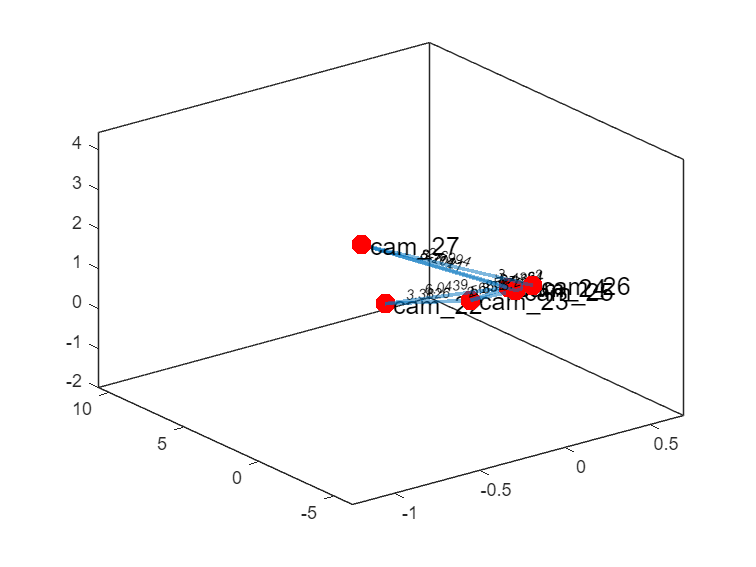

figure(1)

plot(G, 'XData',x,'YData',y,'ZData',z,'NodeLabel', G.Nodes.Name, 'EdgeLabel',G.Edges.Weight, "NodeColor", 'red',  "MarkerSize", 10, "LineWidth", 2, "NodeFontSize", 14, Interpreter="none");

## Set B

Perform same Steps for Set B

imagesB_path = "Test1/SetB/images";
workspaceB_path = "Test1/SetB/Workspace";  % path where colmap will write the model files. 
if(~exist(workspaceB_path, 'dir')), mkdir(workspaceB_path); end

- **Run Colmap for Set A**


colmapB_cmd = sprintf("%s automatic_reconstructor --image_path %s --workspace_path %s ", colmap_exe, imagesB_path, workspaceB_path);
[statusB, outstrB] = system(colmapB_cmd);

if statusB
    error("Failed to perform colmap generation.");
end

- ** Convert model to text**


binary_modelB_path = fullfile(workspaceB_path, "sparse/0/");
txt_modelB_path = fullfile(workspaceB_path, "model_as_text");
if(~exist(txt_modelB_path, 'dir')), mkdir(txt_modelB_path); end
colmap_conv_cmdB = sprintf("%s model_converter --input_path %s --output_path %s --output_type TXT", colmap_exe, binary_modelB_path, txt_modelB_path);
[status3, outstr3] = system(colmap_conv_cmdB);

if status3
    error("Failed to perform colmap conversion.");
end

- **Create Graph**


thresholdB =13

thresholdB = 13

images_txt_fnameB = fullfile(txt_modelB_path, "images.txt");
CamExtrB  = get_camera_extr_params(images_txt_fnameB);
cameraCentersB = get_camera_centers(CamExtrB);
distancesB = get_euclidian_distances(cameraCentersB);

% InvDist = inv(distances); % inverse of distances. 
InvDistB = distancesB;
% threshold = mean(InvDist, "all");
AB = InvDistB;

AB(AB>thresholdB) = 0;

xB = cameraCentersB(:, 1);
yB = cameraCentersB(:, 2); 
zB = cameraCentersB(:, 3); 

no_of_nodesB = numel(CamExtrB);
node_namesB = strings(no_of_nodesB, 1);

for i=1:no_of_nodesB
    image_name = CamExtrB{i}.name; 
    image_name = strrep(image_name, '.jpg', '');
    image_name = strrep(image_name, 'image', 'cam');
    node_namesB(i) = image_name; 
end

GB = graph(AB, 'upper');
GB.Nodes.Name = node_namesB;

- **Plot Graph**

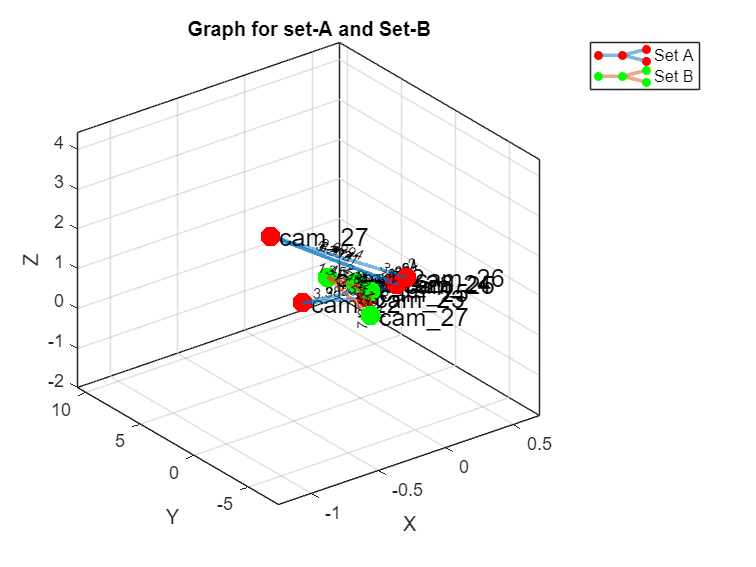

hold on
p= plot(GB, 'XData',xB,'YData',yB,'ZData',zB, 'NodeLabel', GB.Nodes.Name,  'EdgeLabel',GB.Edges.Weight, "NodeColor", 'green',  "MarkerSize", 10, "LineWidth", 2, "NodeFontSize", 14, Interpreter="none");
legend("Set A", "Set B")
grid on
title("Graph for set-A and Set-B")
xlabel("X")
ylabel("Y")
zlabel("Z")
hold off